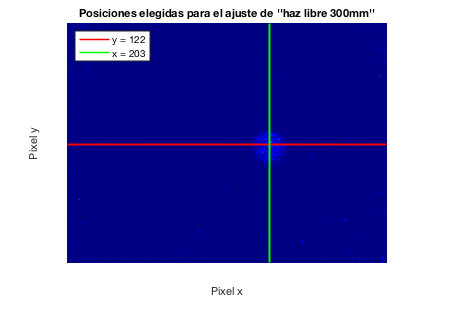

close all;
clear all;

%Carga de imagenes
%Cambiar el nombre segun la imagen a analizar
titulo_img_300 = 'haz_300mm.jpg';
titulo_img_305 = 'haz_305mm.jpg';
titulo_img_310 = 'haz_310mm.jpg';
config = 'libre';%para poner el nombre al grafico

%titulo_img_300 = 'haz_ancho_300mm.jpg';
%titulo_img_305 = 'haz_ancho_305mm.jpg';
%titulo_img_310 = 'haz_ancho_310mm.jpg';
%config = 'ancho';%para poner el nombre al grafico

%titulo_img_300 = 'haz_angosto_300mm.jpg';
%titulo_img_305 = 'haz_angosto_305mm.jpg';
%titulo_img_310 = 'haz_angosto_310mm.jpg';
%config = 'angosto';%para poner el nombre al grafico

%titulo_img_graf = 'haz ancho 300mm';%Lo uso de titulo de figura
%titulo_img_fig = 'haz_ancho_300'; %Lo uso para el nombre al exportar la figura

%titulo_img_fig_config = 'libre'; %es para el nombre al exportar
%titulo_img_fig_config = 'ancho';
%titulo_img_fig_config = 'angosto';

k=75; %iteraciones para buscar el maximo matricial promedio
% Si el centro da mal a ojo, aumentar k 

imagen_300= im2double(rgb2gray(imread(titulo_img_300)));
imagen_305 = im2double(rgb2gray(imread(titulo_img_305)));
imagen_310 = im2double(rgb2gray(imread(titulo_img_310)));

[fil(1) , col(1)] = size (imagen_300);
[fil(2) , col(2)] = size (imagen_305);
[fil(3) , col(3)] = size (imagen_310);

%fila_max = [fila_max_300 fila_max_305 fila_max_310]
%col_max = [col_max_300 col_max_305 col_max_310]
[fila_max(1) col_max(1)] = centro(imagen_300,k);
[fila_max(2) col_max(2)] = centro(imagen_305,k);
[fila_max(3) col_max(3)] = centro(imagen_310,k);

%-------------------------
%Grafico la imagen en falso color y los pixeles xfijo e yfijo donde se hara el ajuste
%300mm
figure();
imshow(gray2ind(imagen_300), jet());
hold on;
plot(1:(col(1)), fila_max(1)*ones(1,col(1)), "-r", "linewidth", 1.5);
plot(col_max(1)*ones(1,fil(1)), 1:(fil(1)), "-g", "linewidth", 1.5);
title(sprintf('Posiciones elegidas para el ajuste de ''''haz %s 300mm''''',config));
xlabel('Pixel x');
ylabel('Pixel y');
legend(sprintf('y = %d',fila_max(1)),sprintf('x = %d',col_max(1)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_300_posiciones',config),'-dpng');

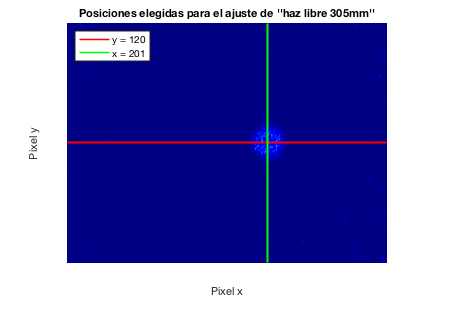


%305mm
figure();
imshow(gray2ind(imagen_305), jet());
hold on;
plot(1:(col(2)), fila_max(2)*ones(1,col(2)), "-r", "linewidth", 1.5);
plot(col_max(2)*ones(1,fil(2)), 1:(fil(2)), "-g", "linewidth", 1.5);
title(sprintf('Posiciones elegidas para el ajuste de ''''haz %s 305mm''''',config));
xlabel('Pixel x');
ylabel('Pixel y');
legend(sprintf('y = %d',fila_max(2)),sprintf('x = %d',col_max(2)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_305_posiciones',config),'-dpng');

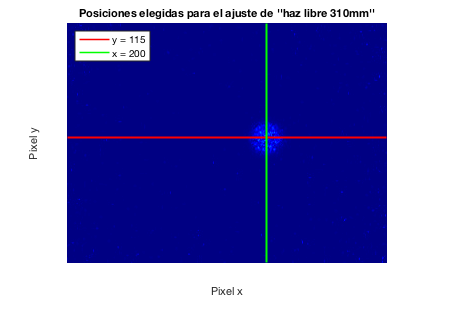


%310mm
figure();
imshow(gray2ind(imagen_310), jet());
hold on;
plot(1:(col(3)), fila_max(3)*ones(1,col(3)), "-r", "linewidth", 1.5);
plot(col_max(3)*ones(1,fil(3)), 1:(fil(3)), "-g", "linewidth", 1.5);
title(sprintf('Posiciones elegidas para el ajuste de ''''haz %s 310mm''''',config));
xlabel('Pixel x');
ylabel('Pixel y');
legend(sprintf('y = %d',fila_max(3)),sprintf('x = %d',col_max(3)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_310_posiciones',config),'-dpng');

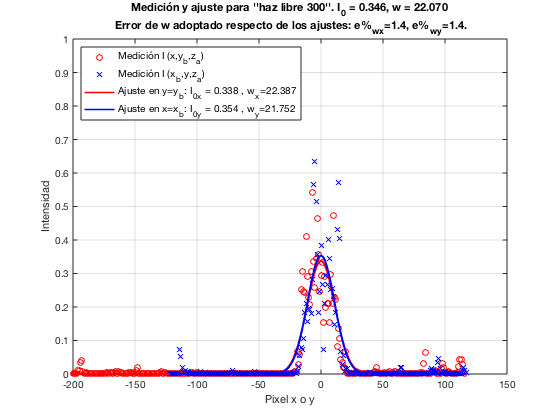


%-------------------------
%--------------------AJUSTE
%Para ajustar en el pixel y=cte uso las siguientes mediciones como variable
%dependiente (ordenada)
med_y(1,:) = imagen_300(fila_max(1),:);
med_y(2,:) = imagen_305(fila_max(2),:);
med_y(3,:) = imagen_310(fila_max(3),:);

%Para ajustar en el pixel x=cte
med_x(1,:) = transpose(imagen_300(:,col_max(1)));
med_x(2,:) = transpose(imagen_305(:,col_max(2)));
med_x(3,:) = transpose(imagen_310(:,col_max(3)));

for i=1:3
    %Estas son las variables indep (abcisas)
    x_0(i,:) = 0 : col(i)-1;
    x_0(i,:) = x_0(i,:) - col_max(i);
    y_0(i,:) = 0 : fil(i)-1;
    y_0(i,:) = y_0(i,:) - fila_max(i);
end

%semilla: [I0 , media=0, w aprox 40] 40pixeles = 1mm
%la semilla es igual para x o y porque voy a arrancar desde el maximo
start(1,:) = [imagen_300(fila_max(1),col_max(1)), 0, 40];
start(2,:) = [imagen_305(fila_max(2),col_max(2)), 0, 40];
start(3,:) = [imagen_310(fila_max(3),col_max(3)), 0, 40];

%Ajustes, la ajusto a la funcion g
g = fittype('I0*exp(-2*((x^2+k^2)/w^2))','independent','x','dependent','y');
%k va a sar chico porque es y_a o x_a [um] 
%En verdad al correr la gaussiana k=0
%en g dice x, pero puede ser x o sino y
fx_300 = fit(x_0(1,:).',med_y(1,:).',g,'startpoint',start(1,:));
fy_300 = fit(y_0(1,:).',med_x(1,:).',g,'startpoint',start(1,:));
fx_305 = fit(x_0(2,:).',med_y(2,:).',g,'startpoint',start(2,:));
fy_305 = fit(y_0(2,:).',med_x(2,:).',g,'startpoint',start(2,:));
fx_310 = fit(x_0(3,:).',med_y(3,:).',g,'startpoint',start(3,:));
fy_310 = fit(y_0(3,:).',med_x(3,:).',g,'startpoint',start(3,:));

%Nomenclatura: [I0 , k , w] = coeffvalues(f) 
Px_300 = coeffvalues(fx_300); %Parametros ajustados en x para y=cte
Py_300 = coeffvalues(fy_300); %Parametros ajustados en y para x=cte
Px_305 = coeffvalues(fx_305);
Py_305 = coeffvalues(fy_305);
Px_310 = coeffvalues(fx_310);
Py_310 = coeffvalues(fy_310);

%Parametros promedio
I0_prom = [ (Px_300(1) + Py_300(1))/2 (Px_305(1) + Py_305(1))/2 (Px_310(1) + Py_310(1))/2];  
w_prom = [ (Px_300(3) + Py_300(3))/2 (Px_305(3) + Py_305(3))/2 (Px_310(3) + Py_310(3))/2];

%Error de w usado respecto de wx,wy, o sea relativo
%Matriz de 3x2, filas = z_a, col = wx,wy
error_wxwy(1,:) = [Px_300(3)/w_prom(1) Py_300(3)/w_prom(1)];   
error_wxwy(2,:) = [Px_305(3)/w_prom(2) Py_305(3)/w_prom(2)];
error_wxwy(3,:) = [Px_310(3)/w_prom(3) Py_310(3)/w_prom(3)];
error_wxwy = abs(100*(1-error_wxwy)); %porcentual

%-------------------------
%Grafico los ajustes y mediciones
%z=300mm
figure();
plot(x_0(1,:),med_y(1,:),'ro',"linewidth", 1.3);
hold on;
grid on;
plot(y_0(1,:),med_x(1,:),'bx',"linewidth", 1.3);
plot(x_0(1,:), Px_300(1)*exp( - 2*((x_0(1,:)).^2 + Px_300(2)^2)/ Px_300(3)^2 ),'-r', 'linewidth',1.5);
plot(y_0(1,:), Py_300(1)*exp( - 2*((y_0(1,:)).^2 + Py_300(2)^2)/ Py_300(3)^2 ),'-b', 'linewidth',1.5);
title(sprintf('Medición y ajuste para ''''haz %s 300''''. I_0 = %.3f, w = %.3f\n Error de w adoptado respecto de los ajustes: e%%_{wx}=%.1f, e%%_{wy}=%.1f.',config,I0_prom(1),w_prom(1),error_wxwy(1,1),error_wxwy(1,2)));
xlabel('Pixel x o y');
ylabel('Intensidad');
axis([-200 150 0 1]);
legend('Medición I (x,y_b,z_a)','Medición I (x_b,y,z_a)',sprintf('Ajuste en y=y_b: I_{0x} = %.3f , w_x=%.3f',Px_300(1),Px_300(3)),sprintf('Ajuste en x=x_b: I_{0y} = %.3f , w_y=%.3f',Py_300(1),Py_300(3)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_300_ajuste',config),'-dpng');

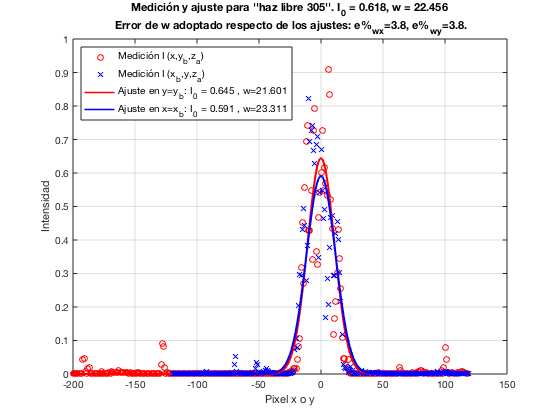


%z=305mm
figure();
plot(x_0(2,:),med_y(2,:),'ro',"linewidth", 1.3);
hold on;
grid on;
plot(y_0(2,:),med_x(2,:),'bx',"linewidth", 1.3);
plot(x_0(2,:), Px_305(1)*exp( - 2*((x_0(2,:)).^2 + Px_305(2)^2)/ Px_305(3)^2 ),'-r', 'linewidth',1.5);
plot(y_0(2,:), Py_305(1)*exp( - 2*((y_0(2,:)).^2 + Py_305(2)^2)/ Py_305(3)^2 ),'-b', 'linewidth',1.5);
title(sprintf('Medición y ajuste para ''''haz %s 305''''. I_0 = %.3f, w = %.3f\n Error de w adoptado respecto de los ajustes: e%%_{wx}=%.1f, e%%_{wy}=%.1f.',config,I0_prom(2),w_prom(2),error_wxwy(2,1),error_wxwy(2,2)));
xlabel('Pixel x o y');
ylabel('Intensidad');
axis([-200 150 0 1]);
legend('Medición I (x,y_b,z_a)','Medición I (x_b,y,z_a)',sprintf('Ajuste en y=y_b: I_0 = %.3f , w=%.3f',Px_305(1),Px_305(3)),sprintf('Ajuste en x=x_b: I_0 = %.3f , w=%.3f',Py_305(1),Py_305(3)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_305_ajuste',config),'-dpng');

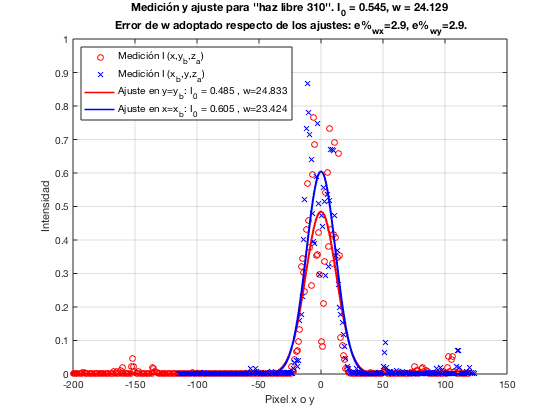


%z=310mm
figure();
plot(x_0(3,:),med_y(3,:),'ro',"linewidth", 1.3);
hold on;
grid on;
plot(y_0(3,:),med_x(3,:),'bx',"linewidth", 1.3);
plot(x_0(3,:), Px_310(1)*exp( - 2*((x_0(3,:)).^2 + Px_310(2)^2)/ Px_310(3)^2 ),'-r', 'linewidth',1.5);
plot(y_0(3,:), Py_310(1)*exp( - 2*((y_0(3,:)).^2 + Py_310(2)^2)/ Py_310(3)^2 ),'-b', 'linewidth',1.5);
title(sprintf('Medición y ajuste para ''''haz %s 310''''. I_0 = %.3f, w = %.3f\n Error de w adoptado respecto de los ajustes: e%%_{wx}=%.1f, e%%_{wy}=%.1f.',config,I0_prom(3),w_prom(3),error_wxwy(3,1),error_wxwy(3,2)));
xlabel('Pixel x o y');
ylabel('Intensidad');
axis([-200 150 0 1]);
legend('Medición I (x,y_b,z_a)','Medición I (x_b,y,z_a)',sprintf('Ajuste en y=y_b: I_0 = %.3f , w=%.3f',Px_310(1),Px_310(3)),sprintf('Ajuste en x=x_b: I_0 = %.3f , w=%.3f',Py_310(1),Py_310(3)),'location','northwest','Fontsize',10);
%print(sprintf('fig_haz_%s_310_ajuste',config),'-dpng');


%El error en pixeles o en mm da igual porque es un factor de escala
%el error de w(z) entre los 3 ajustes lo calculo respecto al de 305mm
%veo la colimacion respecto al primero
%error = [0 error_310 error_310]

error = abs(100* (1 - [w_prom(1)/w_prom(1) w_prom(2)/w_prom(1) w_prom(3)/w_prom(1)]))

error =          0    1.7512    9.3316
